## Манипулятор

% Contact params
st_gripper = 1e6;
b_gripper = 1000;
st_fr_gripper = 0.3;
dyn_fr_gripper = 0.6;
 
%Gripper
gripper_base = 0.10; % m
gripper_finger_l = 0.07;


StopTime = 40;
b = 0.1;
link_dim = 0.05; %m
pin_r = link_dim/2;
pin_l = link_dim;
l1 = 0.3;
l2 = 0.2;
l3 = 0.3;
ee = gripper_base + gripper_finger_l;
m1 = 0.6;
m2 = 0.4;
m3 = 0.3;
m4 = 0.1; %item
q1 = 0;
q2 = pi/2;
q3 = 0;

## Подвеска

Параметры платформы:

%% all parametrs at m
lenght_of_body = 380 * 0.001;
width_of_body = 215 * 0.001;

Параметры звеньев:

Длина

% all lines at m
seed = 115.47 * 0.001;
AB = seed;
BC = seed * 1.296;
CD = seed * 0.489;
EF = seed * 0.828;
EG = seed * 0.599;
HF = EG;
track_width = 0.02;
track_height = 0.02;
density = 1000;
radius_of_pin= 0.01;
length_of_pin= 0.02;

Углы

%% all angles at deg
angle_ABC=30;
ang_BCD=30;
ang_GEF=30;
ang_HFE=ang_GEF;

Ролики

roll_j_d = 0.000001; % roll joint damping
roll_radius = 0.01; % m
rotate = [0; pi/4; pi/2; 3*pi/4; pi; 5*pi/4; 3*pi/2; 7*pi/4; 2*pi];
roll_x_offset = roll_radius * sin(rotate);
roll_y_offset = roll_radius * cos(rotate);
roll_z_offset = zeros(length(roll_x_offset),1);
df = 0.5;

## Контроллер передвижения

% PID_x
kp_x = 15.0;
kd_x = 12.0;
ki_x = 0.0001;
% PID_y
kp_y = 15.0;
kd_y = 10.0;
ki_y = 0.0001;
% PID_yaw
kp_yaw = 15.0;
kd_yaw = 13.0;
ki_yaw = 0.0001;

## **Поверхность**

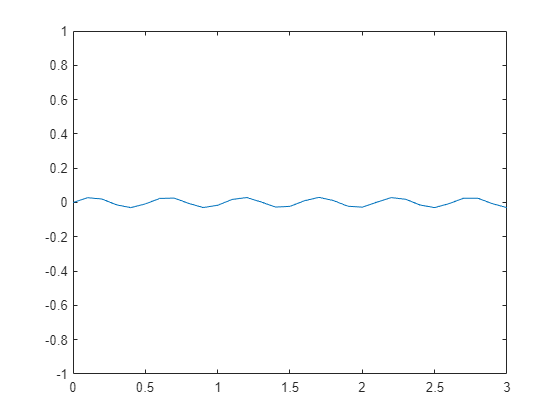

h = 0.03;       %m
step = 0.1;
x_grid = 0 : step : 3;       %m
y_grid = 0 : step : 3;       %m
grid_median_iter = round(length(x_grid)/2,1,'significant');
surface_formula = h * sin(12*x_grid);
z_heights = zeros(length(x_grid),length(y_grid));
for (i = 1:length(x_grid))
    z_heights(i,:) = surface_formula(i);
end

plot(x_grid, surface_formula);
% xlim([1.048 1.358])
ylim([-1 1])